**Demo on using parametric linear models**

What is a parametric linear model?

    The purpose of a parametric linear model is test parameter such as reaction-time, a behavioral metric, or variables such as repetition (in the case of learning/habituation models) on the time-course of the data.  This is a first-level statistical model (e.g. done in the GLM step).  Parameters that can be used are anything that changes over the time of a scan of data.

Examples:

-  Motor-learning.  Use the block number (repetition or time elapsed in the task) as a covariate in the model

- Reaction time, accuracy, or other behavioral metrics that can be assigned to a single event block.  E.g. The subject did 10 blocks of a task; how did the brain activity vary between high and low accuracy blocks?

% For this problem, let's just generate a simple block design 
% simulated data set.  We aren't putting any modulations into
% the simulation, so all of our parametric tests should be null,
% but we can show how to do these models

% In the simData functions, you can pass it a particular stimulus 
% design instead of using the default event related model
% This will take either a specific stimulus dictionary or the funciton
% handle to one of the stimulusgenerating functions.
% Here, we are asking for a block design task with 20s on, 20s off, and 1
% type of tasks.
stimfcn = @(time)nirs.testing.blockedStimDesign(time,20,20,1);
raw = nirs.testing.simData([],stimfcn);

A parametric linear model uses the "amplitude" field in the stimulus events object.  In most studies, this amplitude is just a column of ones, but we can use this to encode hypotheses of how the amplitude of event blocks vary over time.

stim = raw.stimulus('A');
disp(stim);

  StimulusEvents with properties:

                     name: 'A'
                    onset: [30.6002 70.6002 110.6002 150.6002 190.6002 230.6002 270.6002]
                      dur: [20 20 20 20 20 20 20]
                      amp: [1 1 1 1 1 1 1]
    regressor_no_interest: 0
                 metadata: [0×0 table]
                    count: 7




% Let's create a new regressor based on event A, that tests how repeated
% trials of A change the brain activity

stimA_mod = stim;
stimA_mod.amp =[-3 -2 -1 0 1 2 3];
% We are now using a variable amplitude.  The values we are using are
% symetric around 0 (mean 0).  

raw.stimulus('A_mod')=stimA_mod;

raw.draw([]);

We can see we now have two regressors (A and A_mod).  

- A is constant over all blocks.  This regressor will test if the average brain response was non-zero

- A_mod varies per block.  The first block is negative, the second is less negative, the 4th is 0, the last is positive (etc).  This regressor will test if the brain varied linearly across the scan based on repetitions of the task

job = nirs.modules.OpticalDensity;
job = nirs.modules.BeerLambertLaw(job);
job = nirs.modules.Resample(job);
job = nirs.modules.GLM(job);

Stats= job.run(raw);

................................Finished    1 of    1.


  In our stats variable, we now have two terms.  

- A - intepret this as the average brain response across all the blocks.

- A_mod - intepret this as the "slope" of how brain activity varied with repeated trials.  Because we sloped the amplitude up (-3--> +3), a positive effect on this statistic means the brain activity increased with repetition.

If you don't center the variable (e.g. the amplitude is 1,2,3,4,5,6,7 instead of zero-mean), then the slope ("A_mod") will be the same, but now the main term ("A") will reflect the brain response where parameter encoded by amplitude (repetition in this case) is 0.

** Example 2.**

We can modify the ampltude field directly as we just did or there are tools to help us do this.

The tools (which is called "nirs.design.split_parametric") allows us to used several variables

- time (experimental time)

- duration (duration of the event)

- amp (anything encoded on the amp field already)

- metadata (a table on the StimEvents that can encode anything).  Metadata can be continious, ordinal, or categorical.

% Let's clean off what we already did 
raw.stimulus=raw.stimulus.remove('A_mod');

% Let's start by creating some metadata on the events to show the options

metadata.reactiontime = 100+rand(7,1)*20;
metadata.accuracy = rand(7,1);
metadata.correct = (randn(7,1)>.5);
metadata.score = ordinal({'low','medium','high','low','high','low','medium'}',{'low','medium','high'});

metadata=struct2table(metadata);
disp(metadata);

    reactiontime    accuracy    correct    score 
    ____________    ________    _______    ______

       105.43       0.61001      false     medium
       110.46       0.25182      false     high  
       115.71       0.51146      false     low   
       101.85       0.42011      true      medium
       105.44       0.27587      false     low   
       110.98       0.72816      false     medium
       107.87       0.96569      false     high  




stim=raw.stimulus('A');
stim.metadata=metadata;
raw.stimulus('A')=stim;

raw.draw([]);
% We can see, we are back to a simple single regressor.  We added the
% metadata information, but haven't told the code how to use this
% information yet.

data=nirs.design.split_parametric(data,formula,centervariables,normalize)

Inputs: 

- data-  the time-course fNIRS variable (e.g. "raw") 

- formula- a string formula that will be used to make the modulated regressors (see below)

- centervariables (optional; default = true).  If true, this will center the parameter as we did in the first example where we centered the amplitude of the repeated blocks

- normalize (optional; default = true).  If true, it will rescale the values of the parameters.  This will mathmatically be more stable and won't change the T-statistic, but if you want to know the units on the beta (GLM coefficients), you need to unscale.  This does change the interpretation of the variables when you go to the group-level model (e.g. combine the "slopes" from multiple subjects).

The formula:

The formula used in this function is a string that tells the code how to make the regressor.

Examples:

- ?*(1+Amp) -> results in two regressors per original condition name, with the first constant (amp=1) and the second modulated by whatever info was in the Amp field.  The first part ("?") tells the code to do this for every condition type in the scan

- A*(1 + Amp) -->   Same as above, only just do this to a condition named "A"

- A?*(1 + Amp) --> Do this for all conditions that start with "A" (e.g. A1, A2, A3...)

- A*(1+accuracy) --> Any variable names in metadata can be used.  This will now give a constant term (the "1" part) and a term that varies with the continious variable "accuracy" that we added to the metadata table in the last part

- A*(1+accuracy+accuracy^2) --> 3 regressors, a constant, a linear, and a quadric term with accuracy

- A*(correct) --> This will split A into correct and incorrect responses.  "correct" is logical/boolean in the metadata table, so you don't want to also include the intercept term anymore.  Logicals are a special case of categorical variables.  All categorical variables would be done the same as this example  

- A*(score) --> Ordinal variables are cetgorical variables but with order.  E.g. low, medium, high.  Behind the scenes, ordinal variables are modeled as low = X1.  medium = X1 + X2.  high = X1+X2+X3, such that the parameters you estimate are actually the change between levels (e.g. X3 = the change from medium to high).

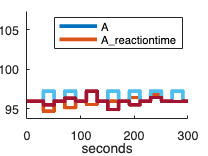

raw = nirs.design.split_parametric(raw,'A*(1+reactiontime)');

raw.draw([]);

% We now have two regressors, the A term is the average brain response and
% the A_reactiontime is how the brain varies with reaction time.  Since
% this is a positive slope, a more positive statistic would mean brain activity went up with higher reaction time

% We can do this again and now split the correct and incorrect responses
raw = nirs.design.split_parametric(raw,'A*(correct)');

% Right now the code DOES NOT remove events, so we have both "A" and
% "A_true" and "A_false" as terms.  Since all events are either true or
% false, we need to get rid of the "A" term

% However, since "A" is the variable that is holding the metadata, we don't
% want to get rid of it till we are fully done with building regressors
% from it.
job=nirs.modules.DiscardStims;
job.listOfStims={'A'};
raw=job.run(raw); 


**Example 3.** 

Time modulation is a bit of a special case.  The previous examples showed how to use the ampltude field to look at parameters that varied by repeated block (e.g. compare how repeat block 1 differs from 2, etc).  But modulation can also be used to look at how the brain varies more continiously too.  For example, how did the brain activity vary over the duration of the a 30s block.

For this, we use the function nirs.design.time_parmod

This does the modulation modules treating amplitude as a continious factor over the events rather and thus uses the StimulusVector class of regressors instead of the StimulusEvents class

Usage:

stim=nirs.design.time_parmod(stim,time,center,reset)

    Inputs:

- stim-  This function takes the StimEvents object rather than the time-course data class

- time-  The modulation variable.  The code should work to use any variable that has the same length as the scan (e.g. an auxillary variable for example), but it was built to deal specifically with time

- center-  A true/false variable of whether or not to center time.  See the dicussion above about centering variables and how this effects interpretion

- rest- A true/false variable of whether to restart for each block or continue across blocks.  For example, if you had a motor learning task with 30second blocks.  For each block, the subject does a DIFFERENT motor sequence and repeats it for the 30s.  Here, you would want reset to be true, because you want to model the learning effect within a 30s block, but then in the next block, you need to relearn the sequence.      

% Let's just create clean dataset to play with
stimfcn = @(time)nirs.testing.blockedStimDesign(time,20,20,1);
raw = nirs.testing.simData([],stimfcn);


center=true;
reset = true;
stim = nirs.design.time_parmod(raw.stimulus('A'),raw.time,center,reset)

stim =   StimulusVector with properties:

                     name: 'A_pmod'
                   vector: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ] (1×3001 double)
                     time: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2 2.1000 2.2000 2.3000 2.4000 2.5000 2.6000 2.7000 2.8000 2.9000 3 3.1000 … ] (1×3001 double)
    regressor_no_interest: 0
      convolve_by_default: 1


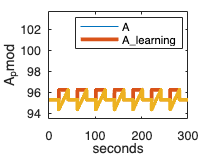


% Note, there is a new field in StimVectors called 
% stim.convolve_by_default 
% This determines the default behavior of whether to convolve with a HRF or
% not.

stim.draw;

raw.stimulus('A_learning')=stim;
raw.draw([]);